# Example 2.5: Pdf and Cdf of Hypergeometric RV

Note: this script reproduces Example 2.5 (Section 2.1.3) of **Statistics for Chemical Engineers**: number of items of a given type in a random sample drawn from a population. Victor Z UW-Madison, 2020 pdf and cdf of a hypergeometric RV

clc; clear all; close all hidden; warning off;

## Pdf

pdf

N=500; % population
n=50;  % sample size
Ny=50; % population of type Y
x=0:1:min(n,Ny);
n=length(x);

for j=1:n
   f(j)=nchoosek(Ny,x(j))*nchoosek(N-Ny,n-x(j))/nchoosek(N,n);
   %f(j)=hygepdf(x(j),N,Ny,n) %matlab built-in function
end

## Cdf

compute cdf empirically, since the cdf formula is too complex

t = 0:1:n+1;
for i=1:length(t)
    F(i)=0;
for j=1:length(x)
    F(i)=F(i)+(x(j)<=t(i))*f(j);
end
% F(i)=hygecdf(t(i),N,Ny,n) %matlab built-in function
end

## Realizations

generate realizations

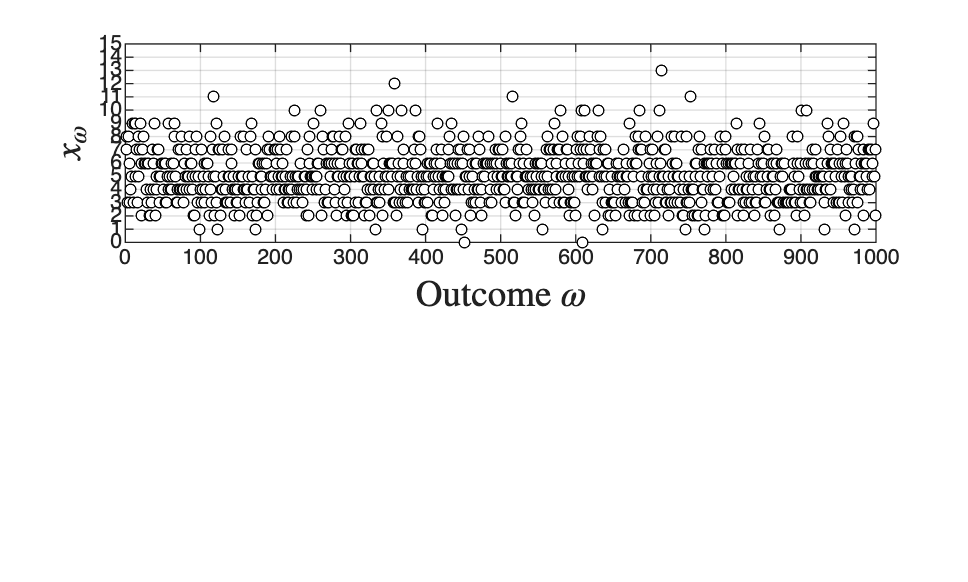

S=1000;
rng(0);
X = hygernd(N,Ny,n,S,1);
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
yticks([0:1:15])
axis([0 S 0 15])


figure(1)

## Plots

visualize pdf

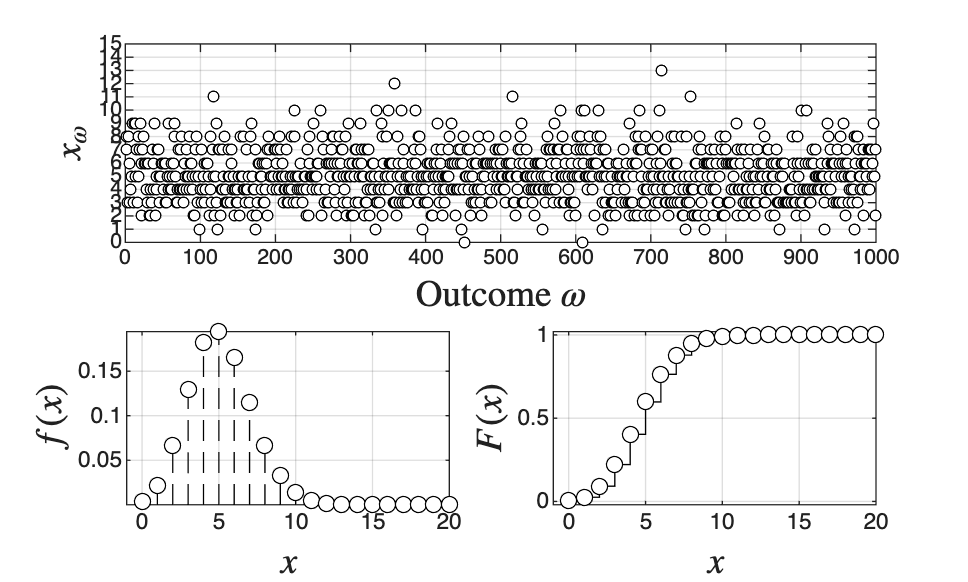

figure(1)
subplot(2,2,3)
for j=1:n
    plot(x(j)*ones(100,1),linspace(0,f(j),100),'black--')
    hold on
end
scatter(x,f,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([min(x)-1 20 min(f) max(f)])

% visualize cdf
subplot(2,2,4)
stairs(t,F,'black-')
hold on
for j=1:n
    scatter(t(j),F(j),'MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
axis([min(x)-1 20 -0.02 1.02])

print -depsc ch2_pdfcdfhypergeo.eps

## Note

As in the book, the probability of finding fewer than 10 items of the type is nearly one; the realizations concentrate around x = 5 and decay quickly, in an asymmetric way.